Starting the black box

[temp, handles] = startBlackBox();

Initializing some variables

signalDataFolder = 'blackBoxData/bodePlot/signals';
numerOfInputCycles = 6;
isTesting = false;
testFrequency = 10e-2;
numberOfFrequencies = 50;
if isTesting
    inputFrequencies = testFrequency;
else
    inputFrequencies = logspace(-4, 4, numberOfFrequencies);
end

Generating signal data for the Bode plot

generateDataForBodePlotParameters = {
    'isTesting';
    isTesting;
    'testFrequency';
    testFrequency
    'destinationFolder';
    signalDataFolder;
    'numerOfInputCycles';
    numerOfInputCycles;
    'inputFrequencies';
    inputFrequencies;
};
generateDataForBodePlot(temp, handles, generateDataForBodePlotParameters{:});

Converting the signal data into magnitude and phase data and saving it.

convertDataToMagAndPhaseParameters = {
    'inputFrequencies';
    inputFrequencies;
    'isPlotting';
    false;
};
[magnitudes, phases] = convertDataToMagAndPhase('blackBoxData\bodePlot\magAndPhases', convertDataToMagAndPhaseParameters{:});

magAndPhaseSaveLoc = 'blackBoxData\bodePlot\magAndPhases\';
bodeDataFileName = 'bodePlotData';

saveBodePlotData(inputFrequencies, magnitudes, phases, magAndPhaseSaveLoc, bodeDataFileName);

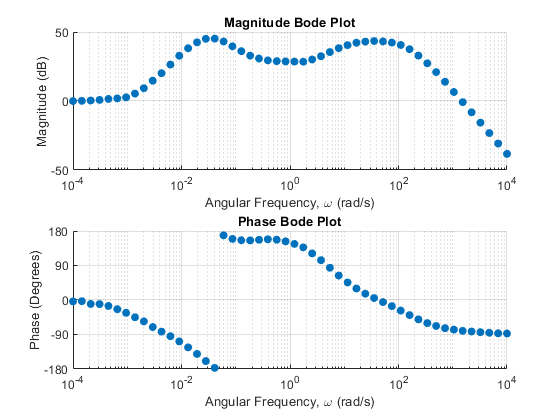

createBodePlots(magAndPhaseSaveLoc, bodeDataFileName);